# Depicting Hinfinity norm subject to sigma

clear;
clc;
close all;

A=[-2 1.35;0 -1];
B=[1;-1];
K=[1 0.65];
D=eye(2);
s=tf('s');
sigma=0:0.01:2.5;
N=numel(sigma)

N = 251

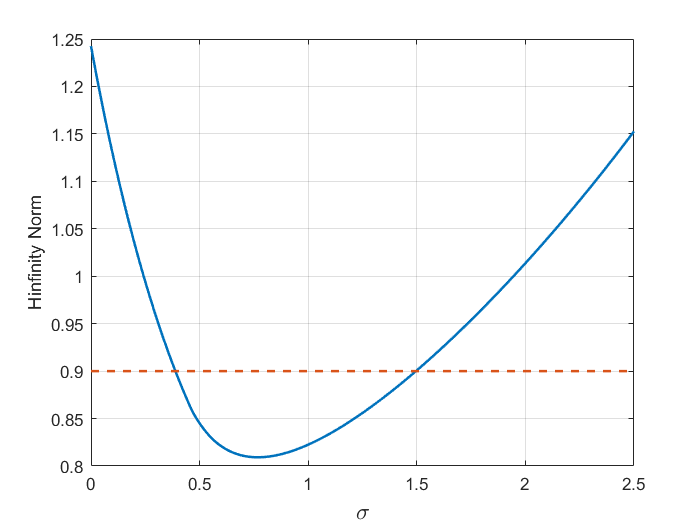

nrm=zeros(1,N);
for i=1:N
    nrm(i)=hinfnorm((s*eye(2)-A-sigma(i)*B*K)^(-1));
end
gamma=0.9*ones(N,1);
plot(sigma,nrm,sigma,gamma,"--",'LineWidth',1.5)
grid on
xlabel('\sigma','FontSize',14)
ylabel('Hinfinity Norm')

clear;
A=[0 1 0 0;-48.6 -1.26 48.6 0;0 0 0 10;1.95 0 -1.95 0];
B=[0;21.6;0;0];
K=[-0.9170 -0.1071 0.5151 -1.1228];
D=eye(4);
s=tf('s');
sigma=0:0.1:30;
N=numel(sigma)

N = 301

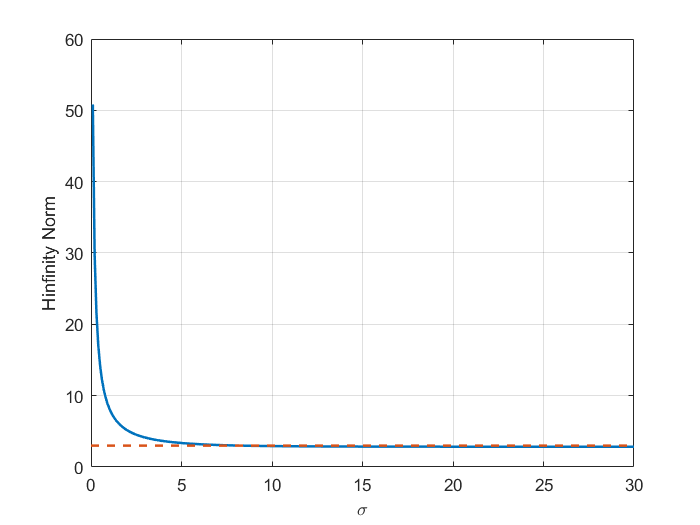

nrm=zeros(1,N);
for i=1:N
    nrm(i)=hinfnorm(D'*(s*eye(4)-A-sigma(i)*B*K)^(-1));
end
gamma=3*ones(N,1);
plot(sigma,nrm,sigma,gamma,"--",'LineWidth',1.5)
grid on
xlabel('\sigma')
ylabel('Hinfinity Norm')